# Project 2.2

## (a) Plot Exact and approximate solutions

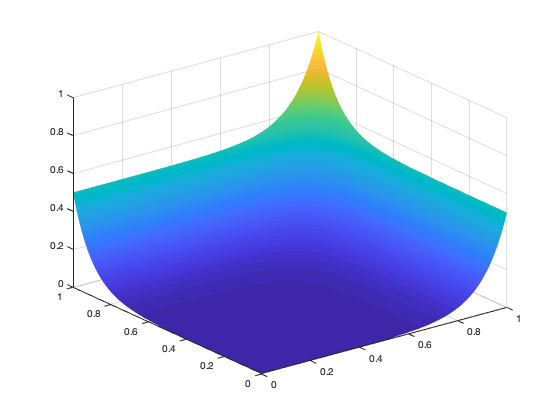

omega = linspace(0,1,1e3);
[MX,MY] = meshgrid(omega,omega);
U = exact_2D(MX,MY,'Problem 2.2     ');
surf(MX,MY,U,'EdgeColor','None')

Mesh 1

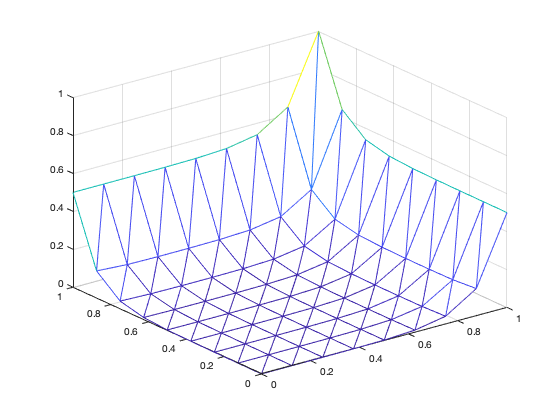

figure()
Global2D();

Mesh 2

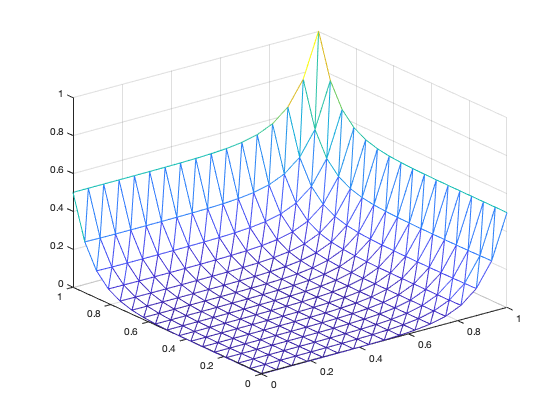

figure()
Global2D();

Mesh 3

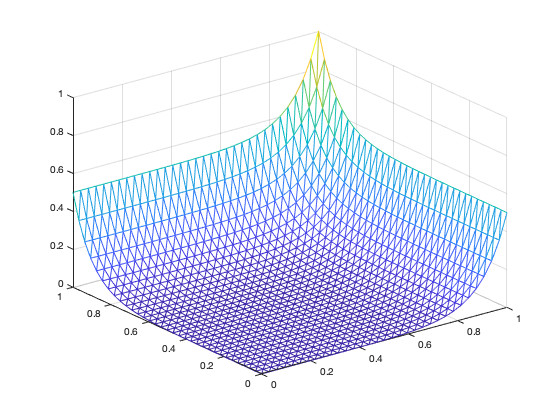

figure()
Global2D();

## (b) Oscillations?

No oscillation is observed near the sharp boundary layer.

I do not expect oscillations because the advective term is missing in this model. The advective term is the main cause of oscillations. So even an sharp layer boundary condition is exhibited, no oscillations are expected.

##  (c) $L_2$ and $L_{\infty}$ error

Mesh 1

L2 = zeros(3,1);
Linf = zeros(3,1);
[L2(1),Linf(1),t(1)] = error2D();

Mesh 2

[L2(2),Linf(2),t(2)] = error2D();

Mesh 3

[L2(3),Linf(3),t(3)] = error2D();
table(["Mesh 1";"Mesh 2";"Mesh 3"],L2,Linf)

ans = 3×3 table
      Var1         L2          Linf   
    ________    _________    _________
    "Mesh 1"     0.019565     0.082496
    "Mesh 2"    0.0050813     0.026714
    "Mesh 3"    0.0012818    0.0076672

## (d) Plot and rate of convergence

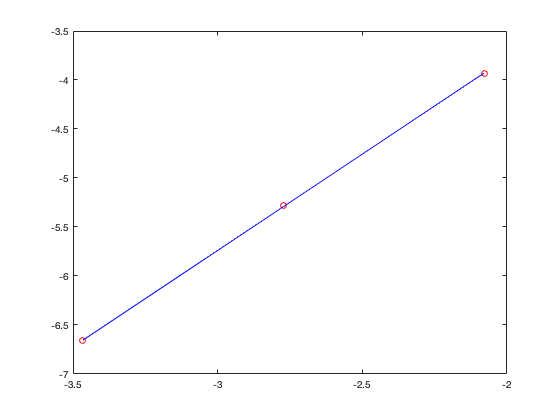

h = [1/8;1/16;1/32]; %spacing for meshes

figure()
plot(log(h),log(L2),'ro')
hold on 
coeffL2 = polyfit(log(h),log(L2),1);
plot(log(h),polyval(coeffL2,log(h)),'b')

slopeL2 = coeffL2(1)

slopeL2 =         1.966

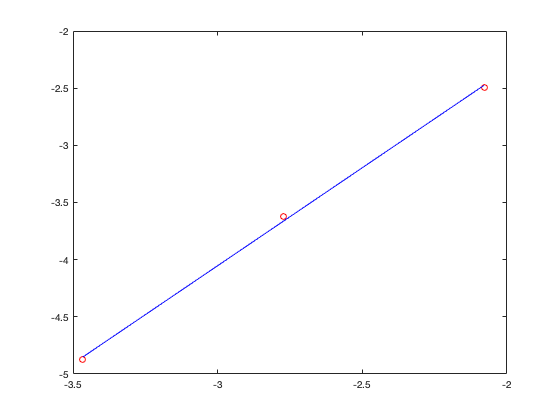



figure()
plot(log(h),log(Linf),'ro')
hold on 
coeffLinf = polyfit(log(h),log(Linf),1);
plot(log(h),polyval(coeffLinf,log(h)),'b')

slopeLinf = coeffLinf(1)

slopeLinf =        1.7138

The rate of convergence of $L_2$ is 1.966, close to 1.9853 in the previous question. But the rate of convergence of $L_{\infty}$ is 1.7138, which is not so close to 1.9894 in the previous question. But both convergence rates are close to 2, the theoretical value.

## (e) Unstructured mesh & Timing

[L2(4),Linf(4),t(4)] = error2D();
table(["Mesh 1";"Mesh 2";"Mesh 3";"Unstructured"],L2,Linf)

ans = 4×3 table
         Var1            L2          Linf   
    ______________    _________    _________
    "Mesh 1"           0.019565     0.082496
    "Mesh 2"          0.0050813     0.026714
    "Mesh 3"          0.0012818    0.0076672
    "Unstructured"    0.0012849    0.0076672

t

t =          0.17         0.34          1.3         0.92


Both error norms of unstructured mesh with 1286 elements are close to those of Mesh 3 in stuctured mesh with 2048 elements. However, the computational time of unstructured mesh is less than that of Mesh 3. Because meshes are not of a fixed shape, unstructure mesh fits the actual shape better and facilates the computation.

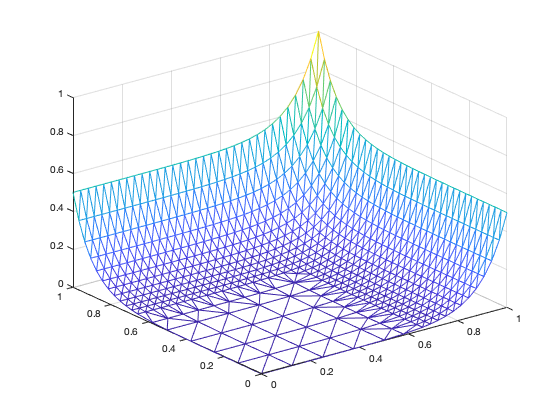

figure()
Global2D();

Taking a closer look at the solution by unstructured mesh, the spacing are larger at z=0 level. The unstructured mesh uses fewer elements while provides the same solution as a structued mesh in a shorter time.